## **Tutorial: Solving a Tensor Least-Squares Problem**

The t-SVDM optimization algorithm for tensor least squares problems introduced in this repository is intended for least squares probelm where we assume that in some transform domain, a linear relationship exists among the frontal slices. For the sake of this tutorial, we construct a toy dataset consisting of tensors A and B for which this is the case. We can make this more realistic by randomly adding some noise into the dataset in the transform domain.

% starMOptSetup

rng(42);
nPoints     = 100;          % number of scatter points
n3          = 2;           % number of parameters
noiseLevel  = 0.005;         % noise in transform domain

% obtaining toy dataset
[A, B] = getToyLeastSquares(nPoints,n3,noiseLevel);

Let's see what our dataset looks like:

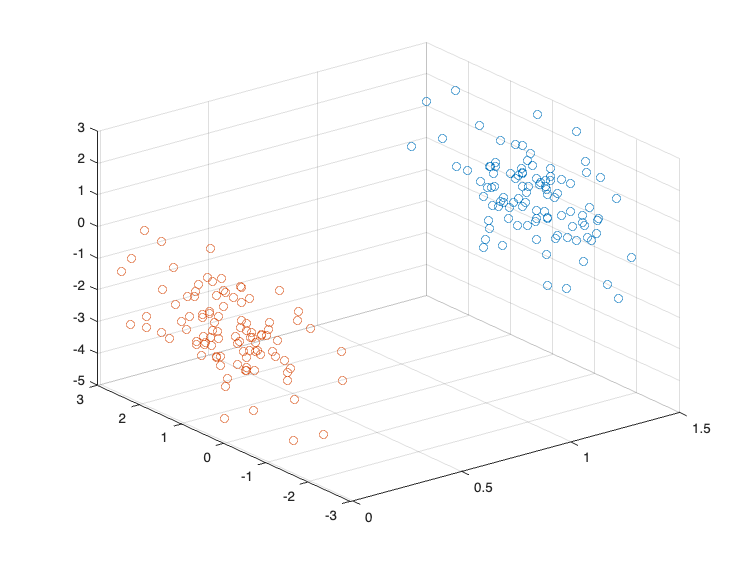

for i = 1:n3
    scatter3(A(:,1,i),A(:,2,i), B(:,1,i));
    hold on;
end
hold off;

In this (spatial) domain, it's not clear that there's a linear relationship (or any relationship) between the $x$ and $y$ variables. The tenOpt repo allows us to find the **optimal** transform domain, given by some transformation matrix $\mathbf{M}^{*}$, that gives a tensor linear relationship (a linear relationship between the respective frontal slices of $\mathcal{A}$ and $\mathcal{B}$) in the transform domain (i.e. a transformation that minimizes the least squares residuals in the transform domain).

First, we define our objective function and our optimizer (gradient descent with an Armijo line search at each (?) iteration - see []).

fctn = objFctnTikhonovLeastSquaresVarPro(A,B);

opt  = gradientDescent('verbose',1,'maxIter',5000,'manifold','Stiefel','logInterval',10,'storeIterates',1);
opt.linesearch = armijoLinesearch('alpha',1e2,'manifold','Stiefel','gamma',1e-3,'maxIter',40);

We use an identity matrix as our initial guess. Note that our optimal transformation $\mathbf{M}^{*}$ is of size $n_{3} \times n_{3}$: the idea of this transformation is that instead of viewing each frontal slice as distinct least squares problems, there is something to be gained by viewing all of the least squares problems together (i.e. that there is some relationship along whatever axis the third dimension represents). 

M0 = eye(n3);

The optimizer then gives us $\mathbf{M}^{*}$.

[MSol,info] = opt.solve(fctn,M0);

iter        Jc          |dJc|       |dJc|/|dJ0| |x1-x0|     alphaLS     iterLS      flagLS      
0           1.04e+00    2.63e+00    1.00e+00    0.00e+00    1.00e+02    0           0           
10          5.59e-05    1.42e-03    5.41e-04    6.91e-05    7.81e-01    1           1           
20          5.59e-05    1.42e-03    5.40e-04    8.79e-07    7.81e-01    1           1           
30          5.59e-05    1.42e-03    5.40e-04    1.12e-08    7.81e-01    1           1           
40          5.59e-05    1.42e-03    5.40e-04    0.00e+00    3.47e-16    41          -1          
Line search break


We now have the optimal transformation $\mathbf{M}^{*}$ for which $\mathcal{A} *_{\mathbf{M}^{*}} \mathcal{X} = \mathcal{B}.$ We can also use this to get $\mathcal{X}$ :

PSol = fctn.solve(MSol);

Let's see how our final loss $\|\mathcal{A} *_{\mathbf{M}^{*}} \mathcal{X} - \mathcal{B}\|_{F}^{2}$ is:

disp(fronorm(mprod(A, PSol, MSol) - B)^2)

    0.0224



This looks good! Finally, let's check our data in the transform domain. We first compute $\hat{\mathcal{A}$ and $\hat{\mathcal{B}$ to see how our original data looks under our optimal transformation:

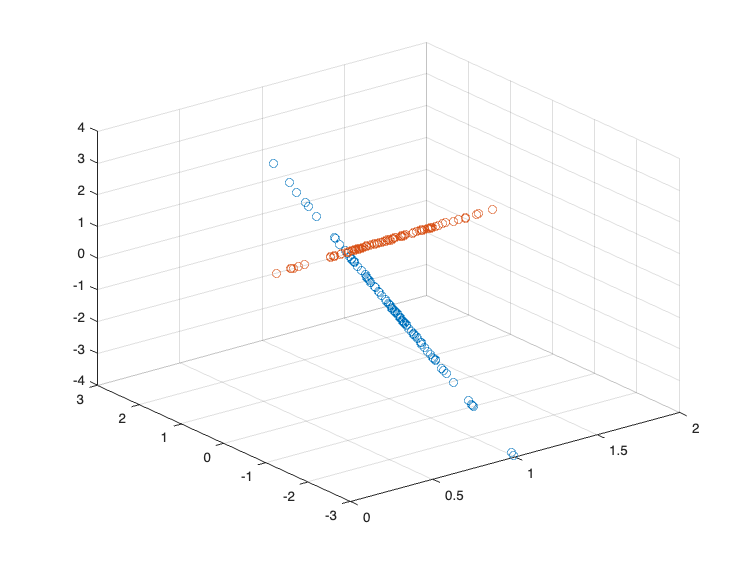

AHat = modeProduct(A,MSol);
BHat = modeProduct(B,MSol);
for i = 1:n3
    scatter3(ones(size(AHat(:,2,i))),AHat(:,2,i), BHat(:,1,i));
    hold on;
end
hold off

With this transformation $\mathbf{M}^{*}$, we clearly get a good linear relationship.

TODO: maybe a plot just showing how PSol looks (probably already in ex_LeastSquares.m)

TODO: possibly check R^2  values for the lines